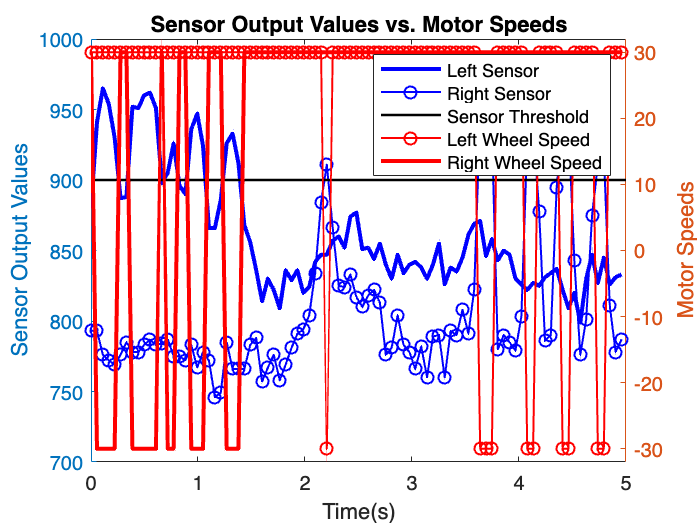

data = [
20008,880,793,30,30;
20064,941,793,30,-30;
20119,965,776,30,-30;
20174,954,772,30,-30;
20229,930,769,30,-30;
20284,887,776,30,30;
20339,888,785,30,30;
20395,952,778,30,-30;
20450,951,778,30,-30;
20504,960,783,30,-30;
20559,962,787,30,-30;
20615,951,783,30,-30;
20670,898,784,30,30;
20725,905,787,30,-30;
20780,926,775,30,-30;
20835,896,775,30,30;
20890,890,772,30,30;
20945,936,783,30,-30;
21001,947,767,30,-30;
21055,924,778,30,-30;
21110,866,772,30,30;
21166,866,746,30,30;
21221,886,749,30,30;
21276,926,785,30,-30;
21331,933,766,30,-30;
21386,912,766,30,-30;
21441,868,766,30,30;
21496,856,783,30,30;
21552,836,788,30,30;
21607,814,757,30,30;
21661,830,767,30,30;
21716,822,776,30,30;
21772,809,758,30,30;
21827,836,769,30,30;
21882,829,781,30,30;
21937,836,791,30,30;
21992,820,794,30,30;
22047,824,804,30,30;
22103,842,834,30,30;
22158,847,884,30,30;
22212,847,911,-30,30;
22267,857,866,30,30;
22323,860,825,30,30;
22378,852,824,30,30;
22432,874,833,30,30;
22488,877,817,30,30;
22543,851,810,30,30;
22598,852,818,30,30;
22653,844,822,30,30;
22708,855,813,30,30;
22763,840,776,30,30;
22818,830,781,30,30;
22874,847,804,30,30;
22929,834,783,30,30;
22984,840,778,30,30;
23038,842,766,30,30;
23094,838,782,30,30;
23149,830,760,30,30;
23204,840,789,30,30;
23260,855,790,30,30;
23314,826,760,30,30;
23369,838,793,30,30;
23425,835,790,30,30;
23480,845,808,30,30;
23535,861,791,30,30;
23589,869,822,30,30;
23645,871,947,-30,30;
23700,846,948,-30,30;
23754,858,937,-30,30;
23810,843,780,30,30;
23865,850,790,30,30;
23920,847,785,30,30;
23975,830,779,30,30;
24030,826,803,30,30;
24085,822,929,-30,30;
24140,827,939,-30,30;
24196,825,878,30,30;
24251,831,786,30,30;
24305,834,790,30,30;
24360,837,895,30,30;
24416,822,940,-30,30;
24471,809,939,-30,30;
24525,820,843,30,30;
24581,799,776,30,30;
24636,830,801,30,30;
24691,847,875,30,30;
24745,827,911,-30,30;
24801,845,918,-30,30;
24856,826,811,30,30;
24911,831,778,30,30;
24967,833,787,30,30;
];
start_time = data(1,1);
time = (data(:,1)- start_time)./1000;
left_sensor = data(:,2);
right_sensor =data(:,3);
left_wheel = data(:,4);
right_wheel = data(:,5);
clf
yyaxis left
plot(time, left_sensor, "b-", LineWidth=2)
hold on
plot(time, right_sensor,"b-o",LineWidth=1)
plot([0, 5], [900, 900], "k-",LineWidth=1.2) 
ylabel("Sensor Output Values")
yyaxis right
ylim([-32,32])
plot(time, left_wheel, "r-o",LineWidth=1)
plot(time, right_wheel, "r-",LineWidth=2)
ylabel("Motor Speeds")
xlabel("Time(s)")
legend("Left Sensor", "Right Sensor","Sensor Threshold", "Left Wheel Speed", "Right Wheel Speed")
title("Sensor Output Values vs. Motor Speeds")